## **Bayesian Optimisation Example**

Goal: *maximise the function f(x) = x.*sin( x );  in the interval [0, 10]*

clear
close all
x = linspace( 0, 10, 501 ).';
f = x.*sin( x );


Extract 7 points for training an initial surrogate model & plot the results:

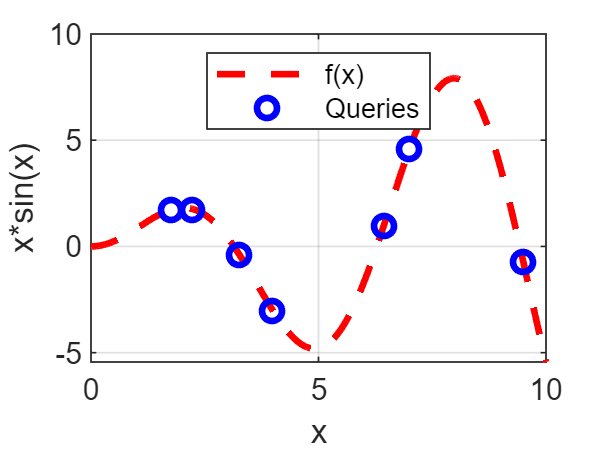

X = [ 9.5, 2.24, 4, 1.76, 3.26, 6.44, 7.0 ].';
Y = X .* sin( X );
plot( x, f, 'r--', X, Y, 'bo', 'LineWidth', 2 );
grid on
xlabel( "x" );
ylabel( "x*sin(x)" );
legend( "f(x)", "Queries", "Location", "north")

Train the initial GP regression model

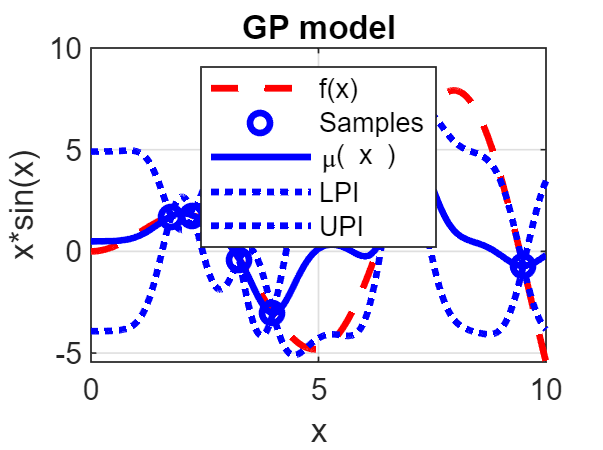

G = gpr( X, Y );
G = G.trainModel();
[ Yp, ~, Yint] = G.predict( x, 0.05 );
close all
figure;
plot(x, f, 'r--', X, Y, 'bo', x, Yp, 'b-', x, Yint( :,1 ), 'b:', x, Yint( :,2 ), 'b:', 'LineWidth', 2);
grid on
legend( "f(x)", "Samples", "\mu( x )", "LPI", "UPI", 'Location', 'north');
xlabel( "x" );
ylabel( "x*sin(x)" );
title( "GP model");

Create an Expected Improvement Acquisition Function object with hyperparameter = 0.02

E = ei( G, 0.02 );
A = E.evalFcn( x );
figure;
plot( x, A, 'g-', 'LineWidth', 2); grid on
xlabel( "x" )
ylabel( "AcqFcn" )
Tstr = sprintf( "Expected Improvement Fcn, \xi = %4.2f", E.Xi );

title( Tstr ); 

Create a bayesian optimisation object and minimise EI(x)

B = bayesOpt( E );
B = B.acqFcnMaxTemplate();

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       2   -7.266226e-03    0.000e+00    7.210e-01
    1       4   -1.074002e-01    0.000e+00    3.509e-01    7.210e-01
    2       6   -2.226229e-01    0.000e+00    5.817e-01    2.360e-01
    3      11   -3.127410e-01    0.000e+00    1.307e-01    2.445e-01
    4      14   -3.140080e-01    0.000e+00    1.454e-02    2.244e-02
    5      16   -3.140254e-01    0.000e+00    8.797e-04    2.246e-03
    6      18   -3.140255e-01    0.000e+00    6.632e-06    1.446e-04
    7      20   -3.140255e-01    0.000e+00    7.183e-09    1.082e-06

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

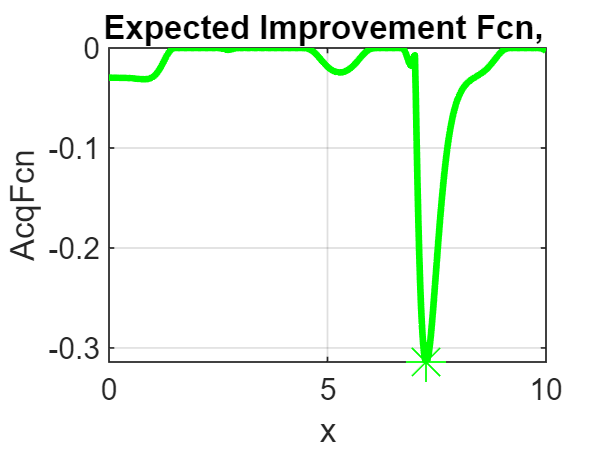

hold on, plot( B.Xnext, B.AcqObj.evalFcn( B.Xnext ), "g*", "MarkerSize", 12 )
grid on
hold off

Query f(x) at the suggested value and update the GP model

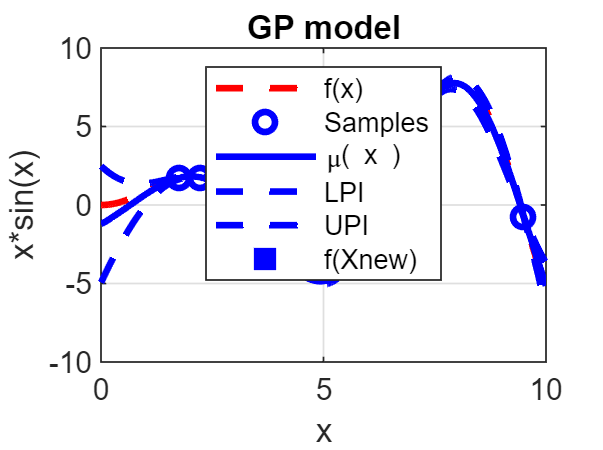

figure;
Xnew = B.Xnext;
Ynew = Xnew * sin( Xnew );
B = B.addNewQuery( Xnew, Ynew );
[ Yp, ~, Yint ] = B.ModelObj.predict( x );
plot(x, f, 'r--', X, Y, 'bo', x, Yp, 'b-', x, Yint( :,1 ), 'b--',...
    x, Yint( :,2 ), 'b--',  'LineWidth', 2);
hold on
plot( Xnew, Ynew, 'bs', 'MarkerSize', 10, 'MarkerFaceColor', 'blue');
grid on
legend( "f(x)", "Samples", "\mu( x )", "LPI", "UPI", "f(Xnew)", 'Location', 'north');
xlabel( "x" );
ylabel( "x*sin(x)" );
title( "GP model");

Now re-potimise the acquisition function

B = B.acqFcnMaxTemplate();

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       2   -5.434956e-03    0.000e+00    1.137e+00
    1       4   -8.994202e-01    0.000e+00    3.621e+00    1.137e+00
    2       6   -1.055051e+00    0.000e+00    3.133e+00    8.655e-01
    3       8   -1.723437e+00    0.000e+00    1.099e-01    4.015e-01
    4      10   -1.724182e+00    0.000e+00    7.991e-03    1.460e-02
    5      12   -1.724186e+00    0.000e+00    1.104e-05    9.893e-04
    6      14   -1.724186e+00    0.000e+00    4.080e-06    1.365e-06
    7      17   -1.724186e+00    0.000e+00    1.200e-06    1.842e-07
    8      19   -1.724186e+00    0.000e+00    2.880e-06    4.185e-08

Local minimum possible. Constraints satisfied.

fmincon stopped because the si

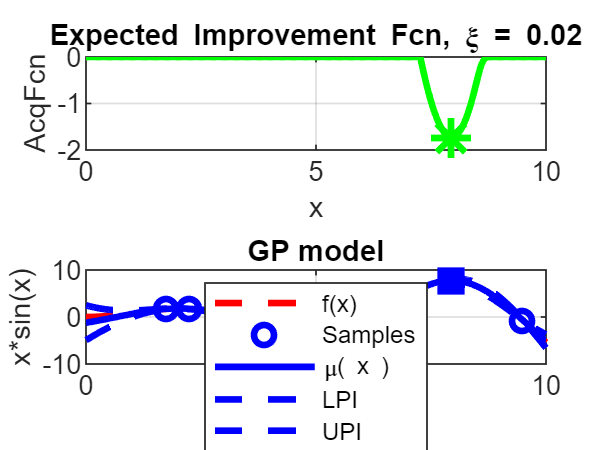

figure;
Xnew = B.Xnext;
subplot(2,1,1), plot( x, B.AcqObj.evalFcn( x ), 'g-', Xnew, B.AcqObj.evalFcn( Xnew ), 'g*', 'MarkerSize', 12,'LineWidth', 2);
grid on
xlabel( "x" )
ylabel( "AcqFcn" )
title( "Expected Improvement Fcn, \xi = 0.02")
subplot(2,1,2)
Xnew = B.Xnext;
Ynew = B.ModelObj.predict( Xnew );
B = B.addNewQuery( Xnew, Ynew );
plot(x, f, 'r--', X, Y, 'bo', x, Yp, 'b-', x, Yint( :,1 ), 'b--',...
    x, Yint( :,2 ), 'b--',  'LineWidth', 2);
hold on
plot( Xnew, Ynew, 'bs', 'MarkerSize', 10, 'MarkerFaceColor', 'blue');
grid on
legend( "f(x)", "Samples", "\mu( x )", "LPI", "UPI", "f(Xnew)", 'Location', 'north');
xlabel( "x" );
ylabel( "x*sin(x)" );
title( "GP model");